syms q1 q2 v1 v2 t1 t2 t3 t4 t5 t6 ddq1 ddq2 dq1 dq2
Ra = 2.6;
b1 = 0.015;
b2 = 0.002;
kt = 0.00768;
kv = 0.00768;
% l1 = (l1+l2')
l1 = 0.2;
l2 = 0.3;
J1 = 0.0012;
m2 = 0.127;
kr = 70;
lc2 = 0.15

lc2 = 0.1500

v2 = 0;


% parameters t is \theta
t1p = J1 + m2*(0.2)^2;
t2p = 1/3*m2*l2^2;
t3p = 1/2*m2*(l1)*l2;
t4p = m2*lc2

t4p = 0.0191


% parameter theta 1~6
t1 = t1p * Ra/(kr*kt)

t1 = 0.0304

t2 = t2p * Ra/(kr*kt)

t2 = 0.0184

t3 = t3p * Ra/(kr*kt)

t3 = 0.0184

t4 = t4p * Ra/(kr*kt)

t4 = 0.0921

t5 = b1 * Ra/(kr*kt) + (kr*kv)

t5 = 0.6101

t6 = b2 * Ra/(kr*kt)

t6 = 0.0097


% vectors & matrices
v = [v1; 0]

$$v = \left(\begin{array}{c} v_{1}\\ 0 \end{array}\right)$$

qdd = [ddq1; ddq2]

$$qdd = \left(\begin{array}{c} {\mathrm{ddq}}_{1}\\ {\mathrm{ddq}}_{2} \end{array}\right)$$

qd = [dq1; dq2]

$$qd = \left(\begin{array}{c} {\mathrm{dq}}_{1}\\ {\mathrm{dq}}_{2} \end{array}\right)$$

M = [t1+t2*sin(q2)^2 t3*cos(q2);
     t3*cos(q2) t2]

$$M = \left(\begin{array}{cc} \frac{1651\,{\sin\left(q_{2}\right)}^{2}}{89600}+\frac{2041}{67200} & \frac{1651\,\cos\left(q_{2}\right)}{89600}\\ \frac{1651\,\cos\left(q_{2}\right)}{89600} & \frac{1651}{89600} \end{array}\right)$$



C = [2*t2*sin(q2)*cos(q2)*dq2 -t3*sin(q2)*dq2;
     -t2*sin(q2)*cos(q2)*dq1    0]

$$C = \left(\begin{array}{cc} \frac{1651\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{2}\right)}{44800} & -\frac{1651\,{\mathrm{dq}}_{2}\,\sin\left(q_{2}\right)}{89600}\\ -\frac{1651\,{\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{2}\right)}{89600} & 0 \end{array}\right)$$


f = [t5*dq1; t6*dq2]

$$f = \left(\begin{array}{c} \frac{2747847186213533\,{\mathrm{dq}}_{1}}{4503599627370496}\\ \frac{13\,{\mathrm{dq}}_{2}}{1344} \end{array}\right)$$


g = [0; t4*sin(q2)]

$$g = \left(\begin{array}{c} 0\\ \frac{1651\,\sin\left(q_{2}\right)}{17920} \end{array}\right)$$


qdd = M\(v-C*qd-f-g) % input torque

$$qdd = \begin{array}{l} \left(\begin{array}{c} \frac{-43567048738996224\,\sin\left(q_{2}\right)\,{{\mathrm{dq}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}-87134097477992448\,\sin\left(q_{2}\right)\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right)-1442619772762104825\,{\mathrm{dq}}_{1}+43567048738996224\,\sin\left(q_{2}\right)\,{{\mathrm{dq}}_{2}}^{2}+22869841857740800\,{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right)+217835243694981120\,\sin\left(q_{2}\right)\,\cos\left(q_{2}\right)+2364389804369510400\,v_{1}}{114349209288704\,\sigma_{1}}\\ -\frac{-16599045569557561344\,{{\mathrm{dq}}_{1}}^{2}\,\cos\left(q_{2}\right)\,{\sin\left(q_{2}\right)}^{3}-27360106608089628672\,{{\mathrm{dq}}_{1}}^{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{2}\right)-33198091139115122688\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,{\cos\left(q_{2}\right)}^{2}\,\sin\left(q_{2}\right)-549638133422361938325\,{\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)+16599045569557561344\,{{\mathrm{dq}}_{2}}^{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{2}\right)+8713409747799244800\,{\mathrm{dq}}_{2}\,{\sin\left(q_{2}\right)}^{2}+14362260686661222400\,{\mathrm{dq}}_{2}+900832515464783462400\,v_{1}\,\cos\left(q_{2}\right)+82995227847787806720\,{\sin\left(q_{2}\right)}^{3}+136800533040448143360\,\sin\left(q_{2}\right)}{43567048738996224\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-381\,{\cos\left(q_{2}\right)}^{2}+381\,{\sin\left(q_{2}\right)}^{2}+628 \end{array}$$



% state space
x = [q1; dq1; q2; dq2];
dx = [dq1; ddq1; dq2; ddq2];


## plotting 

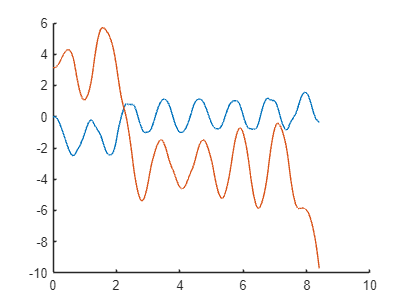

close all
hold on
plot(q1_hil.time, q1_hil.signals.values)
plot(q2_hil.time, q2_hil.signals.values)

hold on

plot(out.q1_sim.time, squeeze(out.q1_sim.signals.values))

Unable to resolve the name 'out.q1_sim.time'.

plot(out.q2_sim.time, squeeze(out.q2_sim.signals.values))
legend('q1 HIL', 'q2 HIL', 'q1 SIM', 'q2 SIM')

